clear all


## Part (a): System State Space Model

% Define System Parameters
Lp = 0.129;
mp = 0.024;
Lr = 0.085;
mr = 0.095;
Jr = (1/3)*mr*Lr^2;
Jp = (1/12)*mp*Lp^2;
Dp = 0.0005;
Dr = 0.0015;
km = 0.042;
Rm = 8.4;

% Let x=[theta alpha thetadot alphadot]'; 
% Define A , B , C , D matrices.
delta = Jr*Jp + mp*(Lr^2)*Jp + (mp*(Lp^2)*Jr)/4;

A = [0 0 1 0;
    0 0 0 1;
    0 ((mp^2)*Lr*(Lp^2)*9.81)/(4*delta) -((Jp + (mp*((Lp^2)/4)))*(Dr + (km^2)/Rm))/delta ...
    -(mp*Lr*Lp*Dp)/(2*delta);
    0 ((Jr + mp*Lr^2)*Lp*mp*9.81)/(2*delta) -(mp*Lr*Lp*(Dr + ((km^2)/Rm)))/(2*delta) ...
    -((Jr + mp*Lr^2)*Dp)/delta];

B = [0;
    0;
    (km*(Jp + ((mp*Lp^2)/4)))/(Rm*delta);
    (km*((mp*Lr*Lp)/2))/(Rm*delta)];

C = eye(4);
D = zeros(4,1);


% Load into state-space system
sys = ss(A,B,C,D);

## Part (b) Pole placement Controller

% Define natural frequencies for the desired performance 
w01=5; % Ronak :5 (rad/sec), Nihal :7 (rad/sec), Criston :9 (rad/sec)
w02=30; % Ronak :30 (rad/sec), Nihal :25 (rad/sec), Criston :40 (rad/sec)

% Find desired eigenvalues for each 2nd order equation
P1=roots([1/w01^2 1.4/w01 1]);% Use 2nd order ITAE prototype with w01
P2=roots([1/w02^2 1.4/w02 1]);% Use 2nd order ITAE prototype with w02

% Concatenate Eigenvalues in one vecor
% this vector defines the 4 desired eigenvalues
P=[P1' P2']; 

% Find desired transfer function
denP=poly(P); % Prototype denominator
gP=tf(denP(end),denP); % Prototype unity gain system

% Use place to find the gain G for the pendulum system
G=place(A,B,P);

% Find the Closed-Loop A matrix, call it Ac
Ac=A-B*G;                    % Closed loop dynamic matrix

% Check the eigenvalues of Ac, they should match P
eig(Ac)                     % Eigenvalue of closed loop system

ans =  -21.0000 +21.4243i
 -21.0000 -21.4243i
  -3.5000 + 3.5707i
  -3.5000 - 3.5707i



% Define the duration of the step response

time=20;

% Define Closed loop system

tf1=zpk(ss(Ac,B,C,0));       % Feedback Transfer function

% Double Check eigenvalues of closd loop sysetm
eig (tf1)                      % Eigenvalue of feedback close loop system

ans =  -21.0000 +21.4243i
 -21.0000 -21.4243i
  -3.5000 + 3.5707i
  -3.5000 - 3.5707i


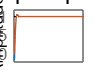


% Define the Dcgain of the closed loop system
N=1/dcgain(tf1);

% Evaluate the Step response of the closed loop system...
% and the desired system on the smae figure. 

step(N*tf1,gP,time)

## Part (c) LQR Controller

Design a state feedback controller for the Inverted Pendulum and evaluate the step response of the closed loop system. Iterate on the values of the elements of Q and R until a 'good' performance is acheived. Use Part (b) for guidance. 

***(Each Student Should Have Their Own Design)***

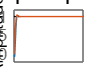

% Define natural frequencies for the desired performance 
w01=5; % Ronak :5 (rad/sec), Nihal :7 (rad/sec), Criston :9 (rad/sec)
w02=30; % Ronak :30 (rad/sec), Nihal :25 (rad/sec), Criston :40 (rad/sec)

% Find desired eigenvalues for each 2nd order equation
P1=roots([1/w01^2 1.4/w01 1]);% Use 2nd order ITAE prototype with w01
P2=roots([1/w02^2 1.4/w02 1]);% Use 2nd order ITAE prototype with w02

% Concatenate Eigenvalues in one vecor
% this vector defines the 4 desired eigenvalues
P=[P1' P2']; 

% Find desired transfer function
denP=poly(P); % Prototype denominator
gP=tf(denP(end),denP); % Prototype unity gain system

Q = [3.5 0 0 0; 0 0 0 0 ; 0 0 0 0 ; 0 0 0 1.55];

R = 0.15;

[G_lqr,~,~] = lqr(A,B,Q,R);

Ac_lqr=A-B*G_lqr;                    % Closed loop dynamic matrix


% Define the duration of the step response

time=20;

% Define Closed loop system

tf1_lqr=zpk(ss(Ac_lqr,B,C,0));       % Feedback Transfer function


% Define the Dcgain of the closed loop system
N_lqr=1/dcgain(tf1_lqr);

% Evaluate the Step response of the closed loop system...
% and the desired system on the smae figure. 

step(N_lqr*tf1_lqr,gP,time)